1/2)

imagefiles = dir('D*.gif');      
nfiles = length(imagefiles);    % Number of files found
altura = 640;
largura = 640;
mkdir novas

for ii=1:nfiles
   currentfilename = "D" + ii + ".gif";
   currentimage = imread(currentfilename);

   novoNome = "novas/D" + ii + "_1" + ".gif";
   imwrite(currentimage(1:altura/2, 1:largura/2),novoNome);

   novoNome = "novas/D" + ii + "_2" + ".gif";
   imwrite(currentimage(1:altura/2, largura/2 + 1 : largura),novoNome);

   novoNome = "novas/D" + ii + "_3" + ".gif";
   imwrite(currentimage(altura/2 + 1 : altura, 1 : largura/2),novoNome);

   novoNome = "novas/D" + ii + "_4" + ".gif";
   imwrite(currentimage(altura/2 + 1 : altura, largura/2 + 1 : largura),novoNome);
   

end

3)

imagefiles = dir('novas/D*.gif');      
nfiles = length(imagefiles);    % Number of files found
altura = 320;
largura = 320;

codigos = zeros(nfiles,256);

for ii=1:nfiles/4
   for jj = 1 : 4
   currentfilename = "D" + ii + "_" + jj + ".gif";
   currentimage = imread("novas/" + currentfilename);
   LBP = zeros(1,256);
   for i = 2 : altura -1
        for j = 2 : largura -1
            hash = 1;
            val = currentimage(i,j);
            
            if val > currentimage(i - 1, j -1)
                hash = hash + 1;
            end
            if val > currentimage(i - 1, j)
                hash = hash + 2;
            end
            if val > currentimage(i - 1, j + 1)
                hash = hash + 4;
            end
            if val > currentimage(i, j + 1)
                hash = hash + 8;
            end
            if val > currentimage(i + 1, j  + 1)
                hash = hash + 16;
            end
            if val > currentimage(i + 1, j)
                hash = hash + 32;
            end
            if val > currentimage(i + 1, j -1)
                hash = hash + 64;
            end
            if val > currentimage(i, j -1)
                hash = hash + 128;
            end
        end

        LBP(hash) = LBP(hash) + 1;
   end
   pos = ((ii - 1) * 4) + jj;
   codigos(pos,:) = LBP(:,:);
   
   

   end
end

Distância Euclidiana

acertos_euclides = 0;
distancia = zeros(nfiles,1);
analisadas = 0;

for i = 1 : 4 : nfiles
    analisadas = analisadas + 1;
    LBP_atual = codigos(i,:);
    [altura,largura] = size(LBP_atual);

    %% calcula a distancia euclidiana para todos os outros LBPS
    for j = 1 : nfiles
        euclides = 0;
        for k = 1 : largura
            x = LBP_atual(1,k);
            y = codigos(j,k);

            euclides = euclides + (x-y) * (x-y);            
        end
        distancia(j,1) = sqrt(euclides);
    end

    %% vai Qual a menor distância
    menor = 32000000000000;
    pos = 0;

    for ii = 1 : nfiles
        if ii ~= i
            if distancia(ii,1) < menor
                menor = distancia(ii,1);
                pos = ii;
            end
        end
    end
    
    %% se foi considerado um acerto ou não
    if pos == i + 1 || pos == i + 2 || pos == i + 3
        acertos_euclides = acertos_euclides + 1;

    end


end

taxa_de_acerto_euclides = acertos_euclides / analisadas;

chi-quadrado

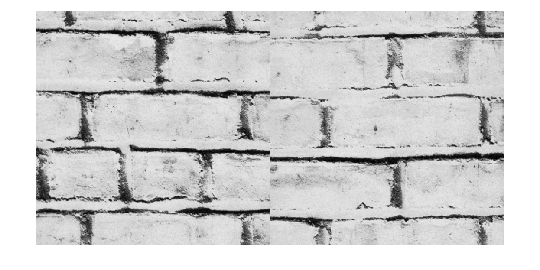

acertos = 0;
distancia = zeros(nfiles,1);
analisadas = 0;
for i = 1 : 4 : nfiles
    analisadas = analisadas + 1;
    LBP_atual = codigos(i,:);
    [altura,largura] = size(LBP_atual);

    %% calcula o chi-quadrado
    for j = 1 : nfiles
        chi = 0;
        for k = 1 : largura
            x = LBP_atual(1,k);
            y = codigos(j,k);
            if x + y ~= 0
            chi = chi + ((x-y) * (x-y))/(x + y);  
            end
                      
        end
        distancia(j,1) = chi * 0.5;
    end

    menor = 32000000000000;
    pos = 0;
     %% vai Qual a menor distância
    for ii = 1 : nfiles
        if ii ~= i
            if distancia(ii,1) < menor
                menor = distancia(ii,1);
                pos = ii;
            end
        end
    end
    %% se foi considerado um acerto ou não
    if pos == i + 1 || pos == i + 2 || pos == i + 3
        acertos = acertos + 1;
  
         montage({"novas/" + imagefiles(i).name,"novas/" + imagefiles(pos).name})
       
    end
end


taxa_de_acerto_chi = acertos / analisadas;